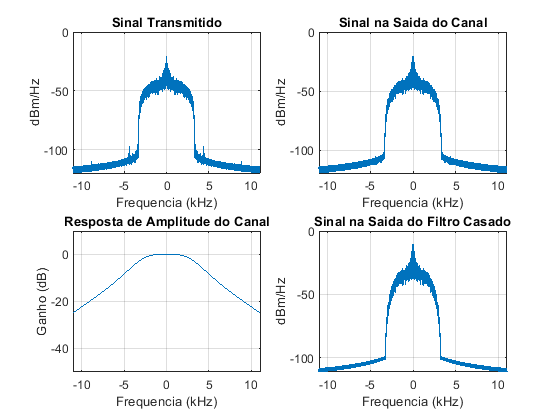





% -------------------------------------------------------------------------
% Simulacao de um Sistema de Transmissao Digital em banda Base
% Será transmitida uma imagem usando simbolos 4-PAM
% -------------------------------------------------------------------------

clear; clc; close all;

% -------------------------------------------------------------------------
% Parametros
% -------------------------------------------------------------------------

Fs=44100;           % Frequencia de Amostragem do Sinal Continuo (Hz)
Ts=1/Fs;            % Periodo de Amostragem (s)

oversampling=10;    % Fator Fs/R

R=Fs/oversampling;  % Taxa de Transmiss?o em s?mbolos/s (baud rate)
T=1/R;              % Periodo de Simbolo (s)

del=25;             % Resposta do filtro formatador se estende por (2*del) periodos de simbolo
                    % Numero de amostras do filtro formatador: N=2*(del*oversampling)+1

rolloff=0.5;        % Fator de rolloff dos filtros Tx e Rx

% -------------------------------------------------------------------------
% Leitura da Imagem e mapeamento 4-PAM
%--------------------------------------------------------------------------

im_in=imread('shuttle_80x60.tif');  %Leitura da imagem a ser transmitida
%im_in=imread('lenna512.tif');

L=8;
[size_r,size_c]=size(im_in);
im_size=size_r*size_c;
im_vec=reshape(im_in,1,im_size);

bit_matrix=de2bi(im_vec);
bit_per_symbol=2;               %constelacao 2^bit_per_symbol-PAM, neste caso 4-PAM
bit_symbols=reshape(bit_matrix, im_size*L/bit_per_symbol, bit_per_symbol);
symbols=bi2de(bit_symbols);     %dibits a ser transmitidos
alphabet=[-3 -1 1 3];           %alfabeto 4-PAM
symbols=symbols+1;
pam=alphabet(symbols);


% -------------------------------------------------------------------------
% Filtro de Tx+Rx
% Formatacao de Pulso - Tipo Raiz Quadrada do Cosseno Levantado no Tx e Rx         
% -------------------------------------------------------------------------
filtro=rcosfir(rolloff,del,oversampling,1,'sqrt');

%Formatar e transmitir os s?mbolos PAM

sinal_tx=upsample(pam,oversampling);           % Realiza Upsampling
sinal_tx_filtrado=conv(sinal_tx,filtro);       % Sinal Filtrado de Transmissao

% -------------------------------------------------------------------------
% Canal Passa Baixas Simulado usando um Filtro de Butterworth
% -------------------------------------------------------------------------

fc=R/2*(1+rolloff);                 % Largura de banda do sinal transmitido
[bn,an]=butter(2,2*fc/Fs);          % Filtro passa-baixas de largura de banda fc
sinal_rx=filtfilt(bn,an,sinal_tx_filtrado);

figure(1);

subplot(2,2,1);                    

% Densidade Espectral de Pot?ncia do Sinal Transmitido
[Pxx,F]=pwelch(sinal_tx_filtrado/max(abs(sinal_tx_filtrado)),[],[],[],Fs,'twosided');
plot((F-Fs/2)/1000,10*log10(fftshift(Pxx))); 
grid; xlabel('Frequencia (kHz)'); ylabel('dBm/Hz');
xlim([-(Fs/4)/1000 (Fs/4)/1000]);
title('Sinal Transmitido')

subplot(2,2,2);                    

% Densidade Espectral de Pot?ncia do sinal recebido
[Pxx,F]=pwelch(sinal_rx/max(abs(sinal_rx)),[],[],[],Fs,'twosided');
plot((F-Fs/2)/1000,10*log10(fftshift(Pxx))); 
grid; xlabel('Frequencia (kHz)'); ylabel('dBm/Hz');
xlim([-(Fs/4)/1000 (Fs/4)/1000]);
title('Sinal na Saida do Canal')

% -------------------------------------------------------------------------
% Receptor (Filtro Casado)
% -------------------------------------------------------------------------

sinal_rx_casado=conv(sinal_rx,filtro);       %Filtro casado


subplot(2,2,3);
[H,F]=freqz(bn,an,2048,'whole',Fs);
gain=20*log10(fftshift(abs(H)));
plot((F-Fs/2)/1000,gain); grid;
axis([-Fs/(4*1000) Fs/(4*1000) -50 10]);
xlabel('Frequencia (kHz)');
ylabel('Ganho (dB)');
title('Resposta de Amplitude do Canal');


subplot(2,2,4);                    

% Densidade Espectral de Pot?ncia do sinal recebido
[Pxx,F]=pwelch(sinal_rx_casado/max(abs(sinal_rx)),[],[],[],Fs,'twosided');
plot((F-Fs/2)/1000,10*log10(fftshift(Pxx))); 
grid; xlabel('Frequencia (kHz)'); ylabel('dBm/Hz');
xlim([-(Fs/4)/1000 (Fs/4)/1000]);
title('Sinal na Saida do Filtro Casado')


pam_rx=downsample(sinal_rx_casado,oversampling);     
pam_rx=pam_rx(del*2+1:length(pam_rx)-del*2);        

%Estimacaoo dos simbolos PAM recebidos

symbols_rx_quant=quantalph(pam_rx,alphabet);

a=[0 1 2 3];
symbols_rx=(symbols_rx_quant+3)/2+1;
symbols_rx=a(symbols_rx);                      %Reconstrucao da imagem no receptor
bit_symbols_rx=de2bi(symbols_rx);
bit_matrix_rx=reshape(bit_symbols_rx, im_size, L);
im_vec_rx=bi2de(bit_matrix_rx);
%im_vec=reshape(im_in,1,im_size);
im_in_rx=reshape(im_vec_rx,size_r,size_c);     

figure(2);

subplot(2,1,1);        %Visualizacao da imagem transmitida
colormap(gray);
h=image(im_in);
set(h,'CDataMapping','scaled')
axis('equal');
title('Imagem Transmitida');
hold;

Current plot held


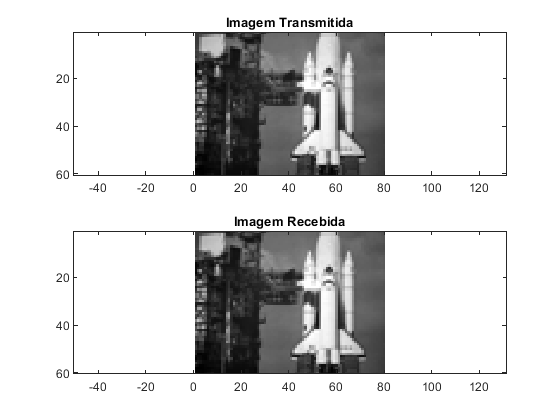


subplot(2,1,2);                                %Visualizacao da imagem recebida
colormap(gray);
h=image(im_in_rx);
set(h,'CDataMapping','scaled')
axis('equal');
title('Imagem Recebida');

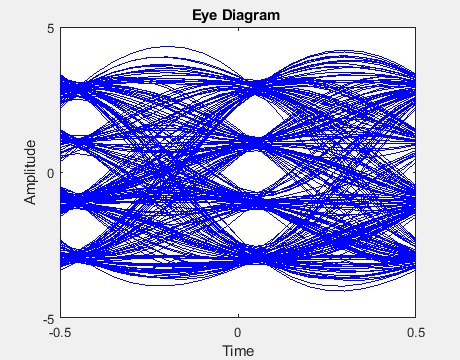


eyediagram(sinal_rx_casado(1,1000:6000),2*oversampling)             %Diagrama de olho

[num_erros,BER]=symerr(bit_matrix_rx,bit_matrix)

num_erros = 0

BER = 0

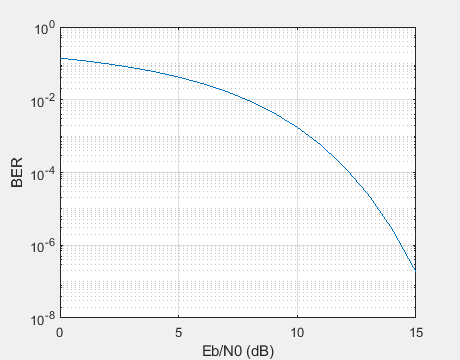





%----------------------------------
M=4; EbN0=[0:1:15];
for k=1:1:length(EbN0);
EavN0=(log2(M))*(10^(EbN0(k)/10));
Pe(k)=(1-1/M)*erfc(sqrt(3*EavN0/(M^2-1)));
BER(k)=Pe(k)/log2(M);
end
semilogy(EbN0,BER);
xlabel('Eb/N0 (dB)');
ylabel ('BER');
grid